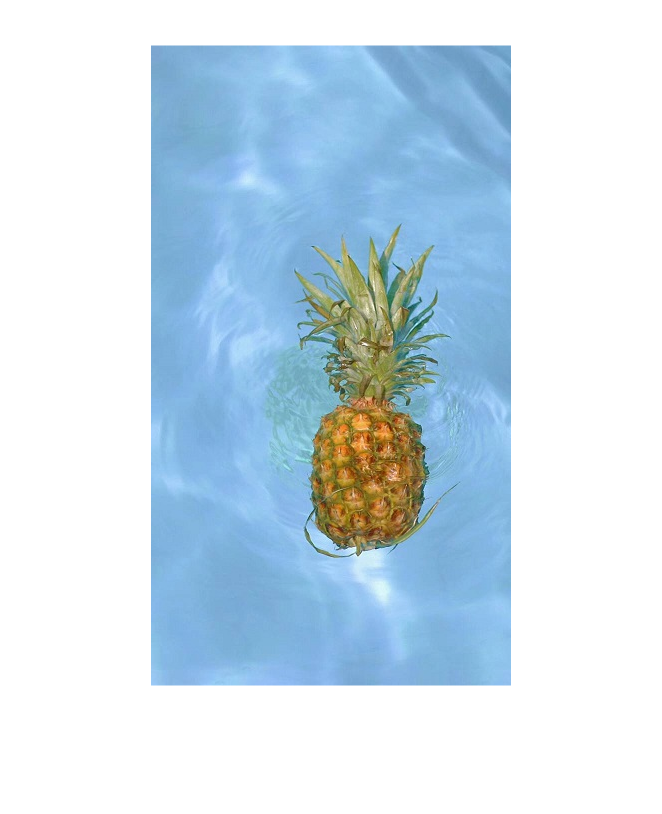

f=imread('./TestPhotos/fruits.jpg','jpg');
imshow(f);

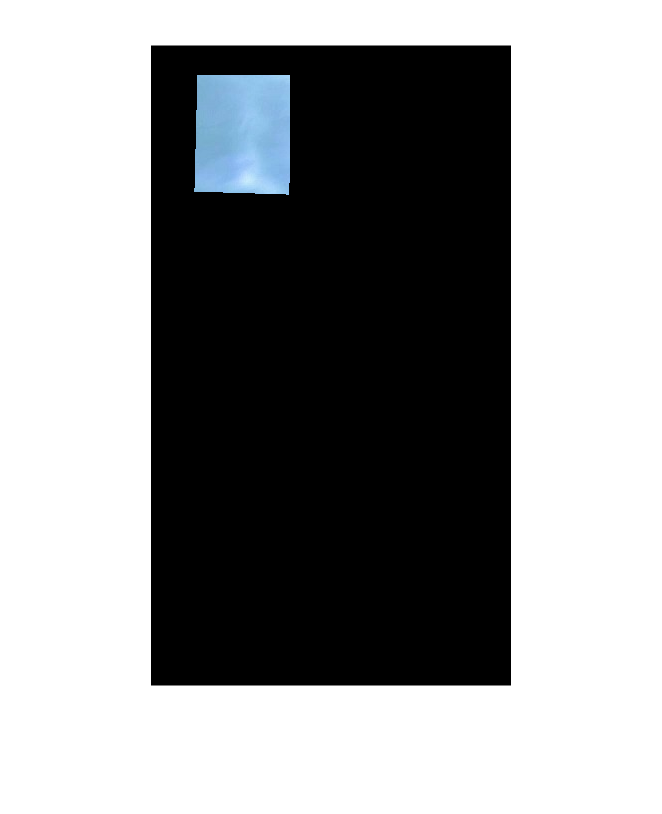

mask=roipoly(f); %采用交互式的方式提取感兴趣的区域ROI
red=immultiply(mask, f(:, :, 1));
green=immultiply(mask, f(:, :, 2));
blue=immultiply(mask, f(:, :, 3));
g=cat(3, red, green, blue);
figure; imshow(g); %显示感兴趣的区域

 
[M, N, K]=size(g);
I=reshape(g, M*N, 3);
idx=find(mask);
I= double(I(idx, 1:3));
[C, m]=covmatrix(I); %计算ROI的协方差矩阵和均值
d=diag(C);
sd=sqrt(d); %计算ROI中RGB个分量的标准差
 
E25=colorseg('eclidean', f, 25, m) %25是根据最大标准差而取，通常为最大标准差的倍数。按照欧式距离计算

E25 =      0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     1     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1     0     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     1     1     1     1     1     1     1     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

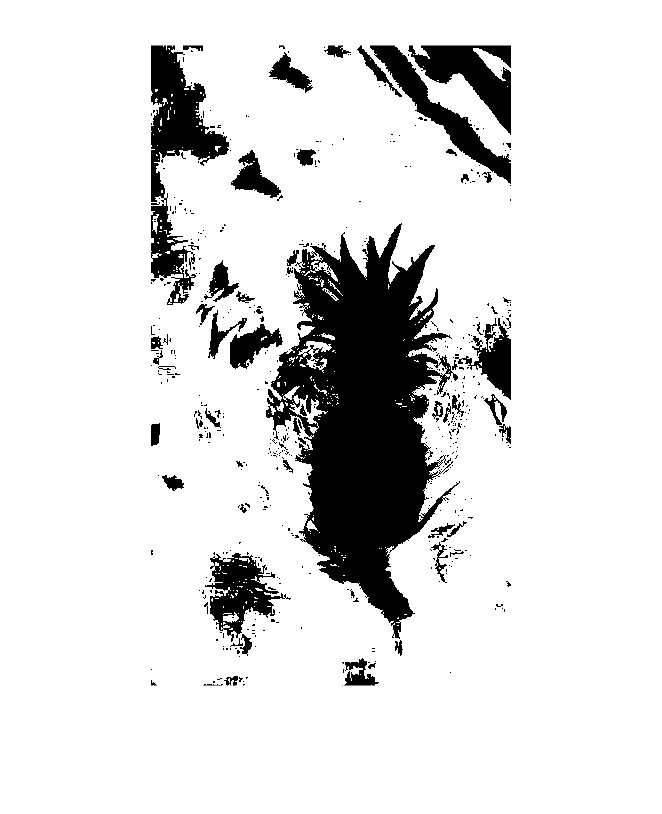

figure; imshow(E25);

 
E25=colorseg('mahalanobis', f, 25, m) %25是根据最大标准差而取，通常为最大标准差的倍数。按照马氏距离计算

E25 =      0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     1     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1     0     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     1     1     1     1     1     1     1     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

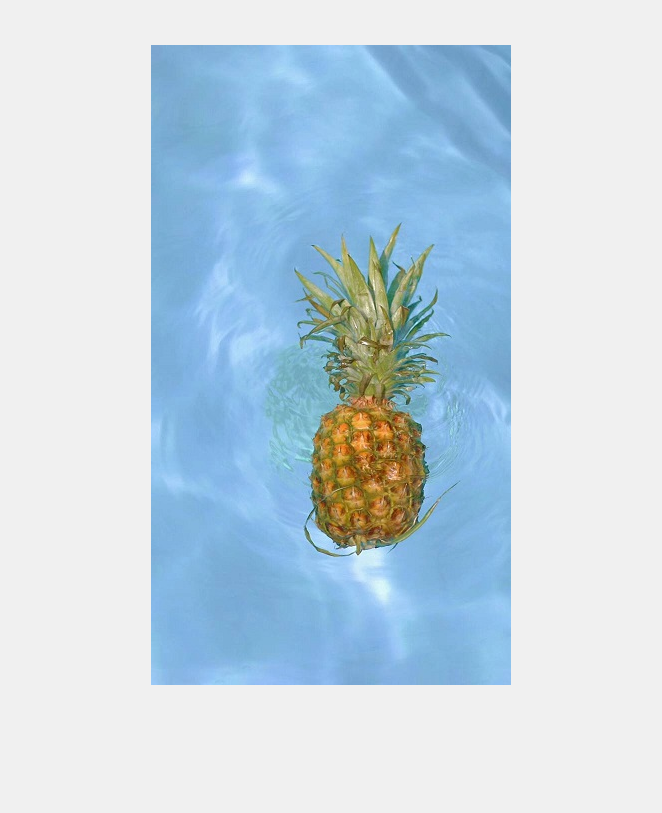

figure; imshow(E25)